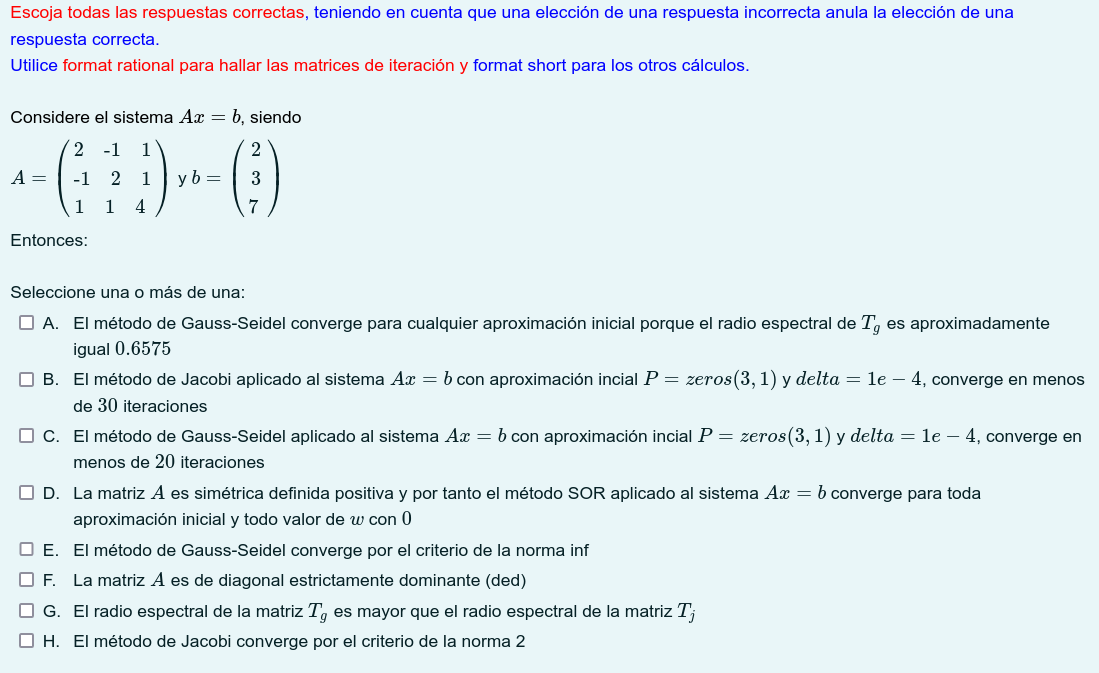

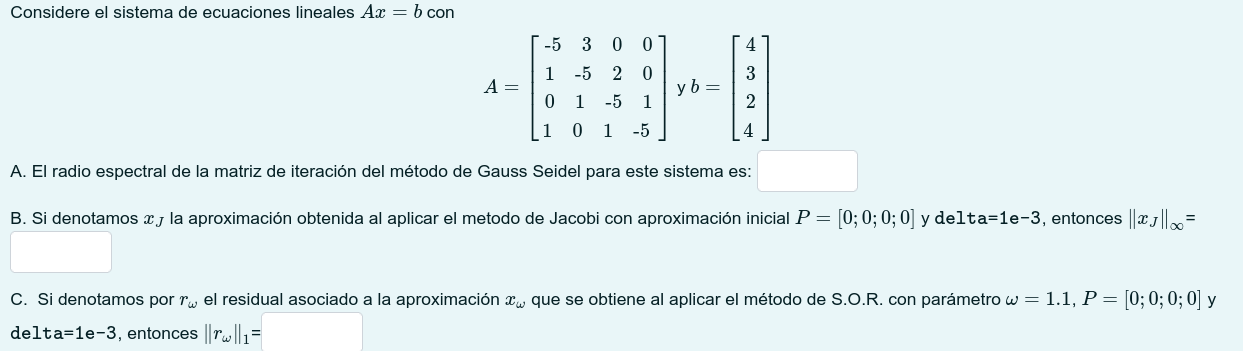

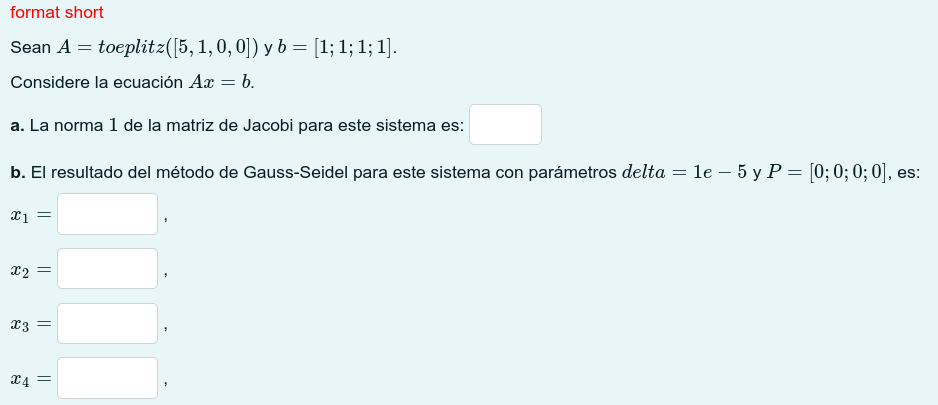


clear
A = toeplitz([5,1,0,0])

A =      5     1     0     0
     1     5     1     0
     0     1     5     1
     0     0     1     5


b = ones(4,1)

b =      1
     1
     1
     1



I = diag(diag(A))

I =      5     0     0     0
     0     5     0     0
     0     0     5     0
     0     0     0     5


U = triu(A) - I

U =      0     1     0     0
     0     0     1     0
     0     0     0     1
     0     0     0     0


L = tril(A) - I

L =      0     0     0     0
     1     0     0     0
     0     1     0     0
     0     0     1     0



J = -inv(I)*(U+L)

J =          0   -0.2000         0         0
   -0.2000         0   -0.2000         0
         0   -0.2000         0   -0.2000
         0         0   -0.2000         0


norm(J,1)

ans = 0.4000


X = gseid (A, b, [0;0;0;0], 1e-5, 1000)

k = 7

X =     0.1724
    0.1379
    0.1379
    0.1724


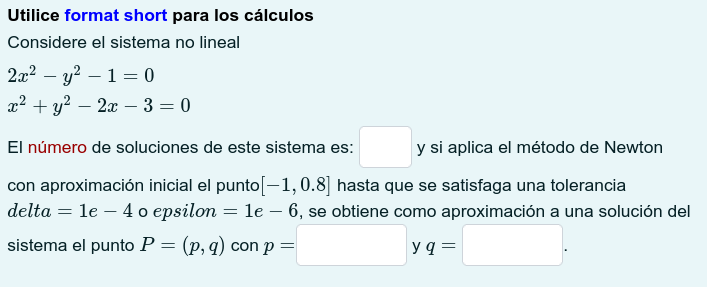

clear
syms f1(x,y)
syms f2(x,y)

f1(x,y) = 2*x^2 - y^2 -1

$$f1(x, y) = 2\,x^{2}-y^{2}-1$$

f2(x,y) = x^2 + y^2 -2*x -3

$$f2(x, y) = x^{2}-2\,x+y^{2}-3$$


f1 = matlabFunction(f1(x,y))

f1 = function_handle with value:
    @(x,y)x.^2.*2.0-y.^2-1.0


f2 = matlabFunction(f2(x,y))

f2 = function_handle with value:
    @(x,y)x.*-2.0+x.^2+y.^2-3.0



uno = ezplot(f1)

uno =   Contour with properties:

    EdgeColor: 'flat'
    LineStyle: '-'
    LineWidth: 0.5000
    FaceColor: 'none'
    LevelList: 0
        XData: [-6.2832 -6.2329 -6.1827 -6.1324 -6.0821 -6.0319 -5.9816 -5.9313 -5.8811 -5.8308 -5.7805 -5.7303 -5.6800 -5.6297 -5.5795 -5.5292 -5.4789 -5.4287 -5.3784 -5.3281 -5.2779 -5.2276 -5.1773 -5.1271 -5.0768 -5.0265 -4.9763 … ] (1×251 double)
        YData: [251×1 double]
        ZData: [251×251 double]

  Show all properties


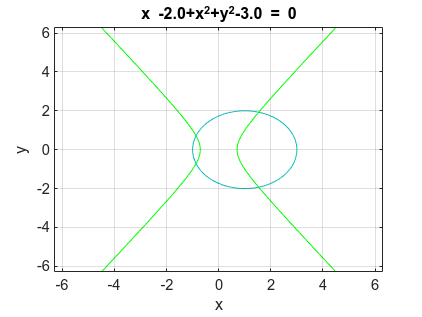

ezplot(f2)
hold on
grid on
set(uno,'color',[0,1,0])


diffx1 = diff(f1,x)

$$diffx1 = 4\,x$$

diffy1 = diff(f1,y)

$$diffy1 = -2\,y$$

diffx2 = diff(f2,x)

$$diffx2 = 2\,x-2$$

diffy2 = diff(f2,y)

$$diffy2 = 2\,y$$


F = @(x)[x(1)^2*2-x(2)^2-1.0, x(1)^2+x(2)^2 - 2*x(1)-3]

F = function_handle with value:
    @(x)[x(1)^2*2-x(2)^2-1.0,x(1)^2+x(2)^2-2*x(1)-3]



JF = @(x)[4*x(1),-2*x(2);2*x(1) - 2,2*x(2)]

JF = function_handle with value:
    @(x)[4*x(1),-2*x(2);2*x(1)-2,2*x(2)]


[P, iter, err] = newdim (F, JF, [-1,0.8], 1e-4, 1e-6, 100)

P =    -0.8685    0.7132


iter = 3

err = 2.3588e-05